# Distillation Example

This example investigates the robustness of a simple model for a distillation column.

The example is taken from Section 3.7.2 of the following reference:

*Skogestad and Postlethwaite, "Multivariable Feedback Control: Analysis and Design", Wiley, 2nd Edition, 2005.*

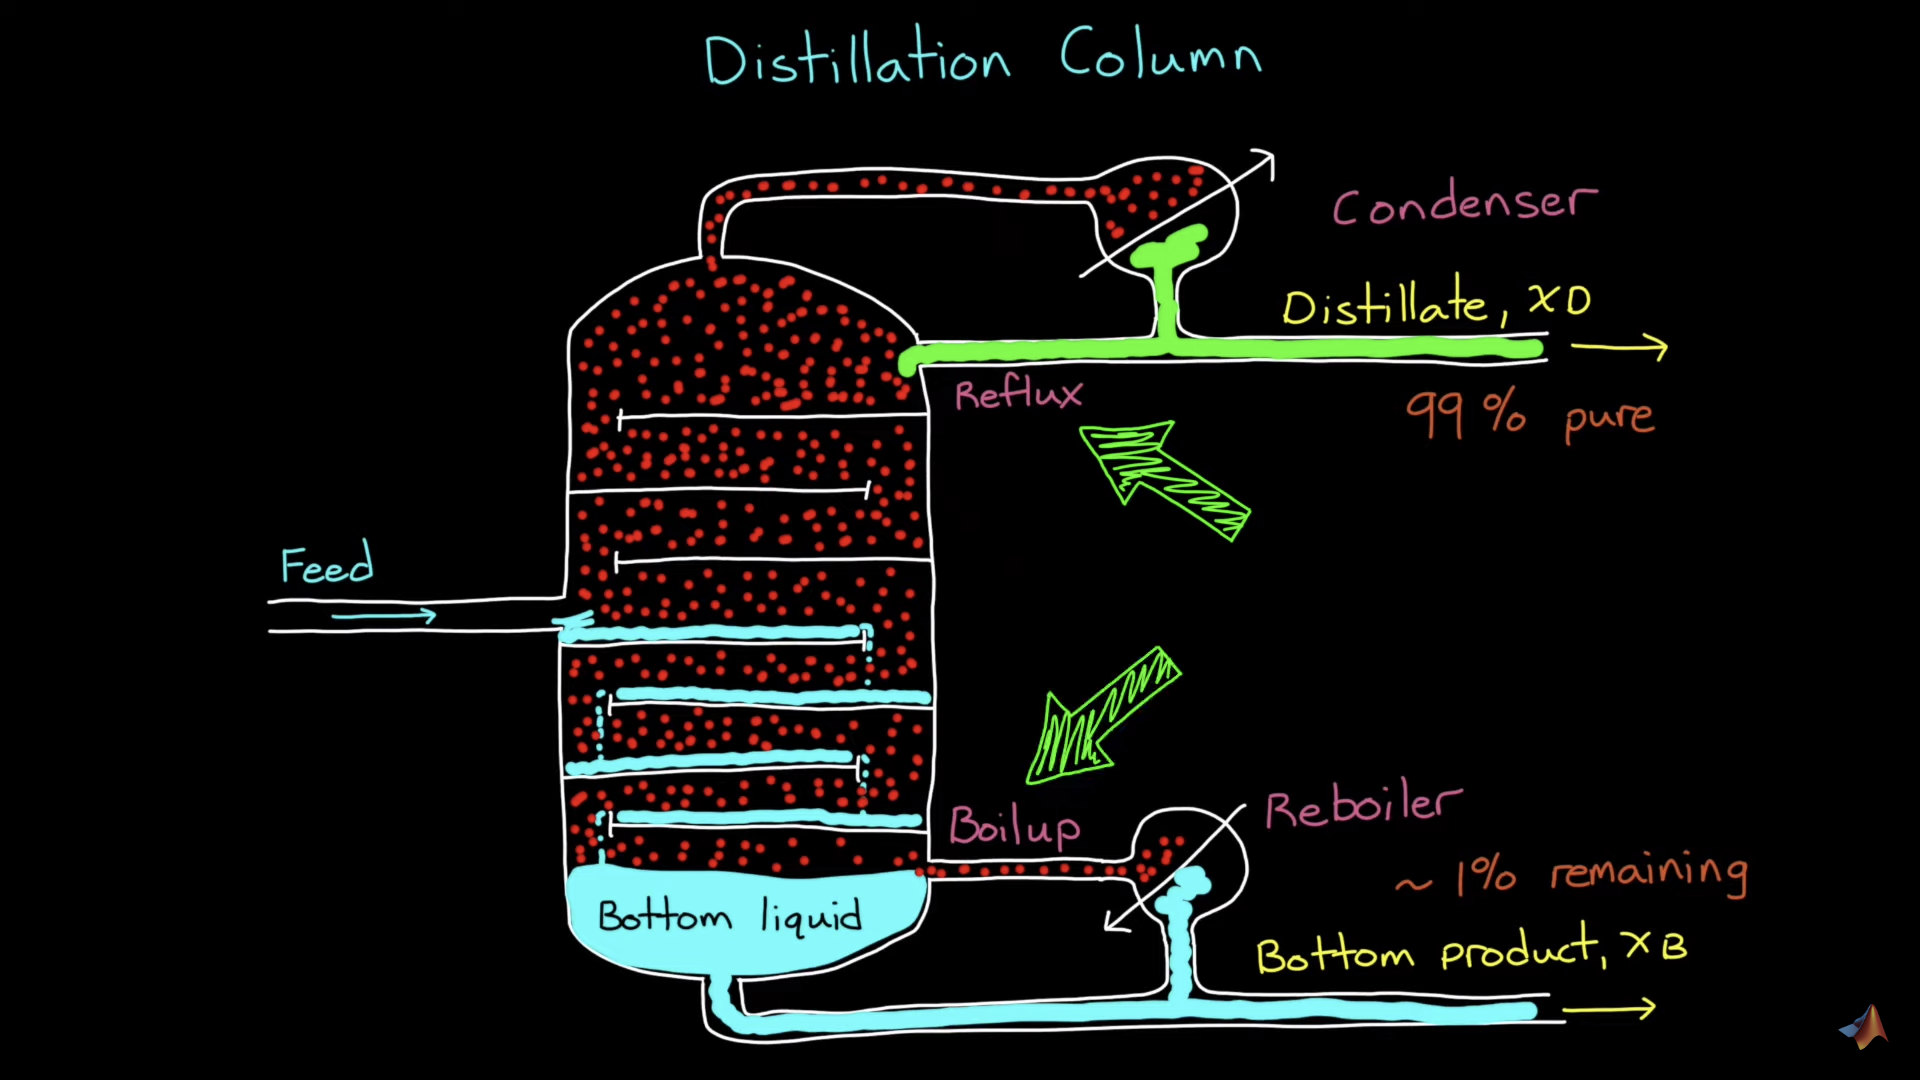

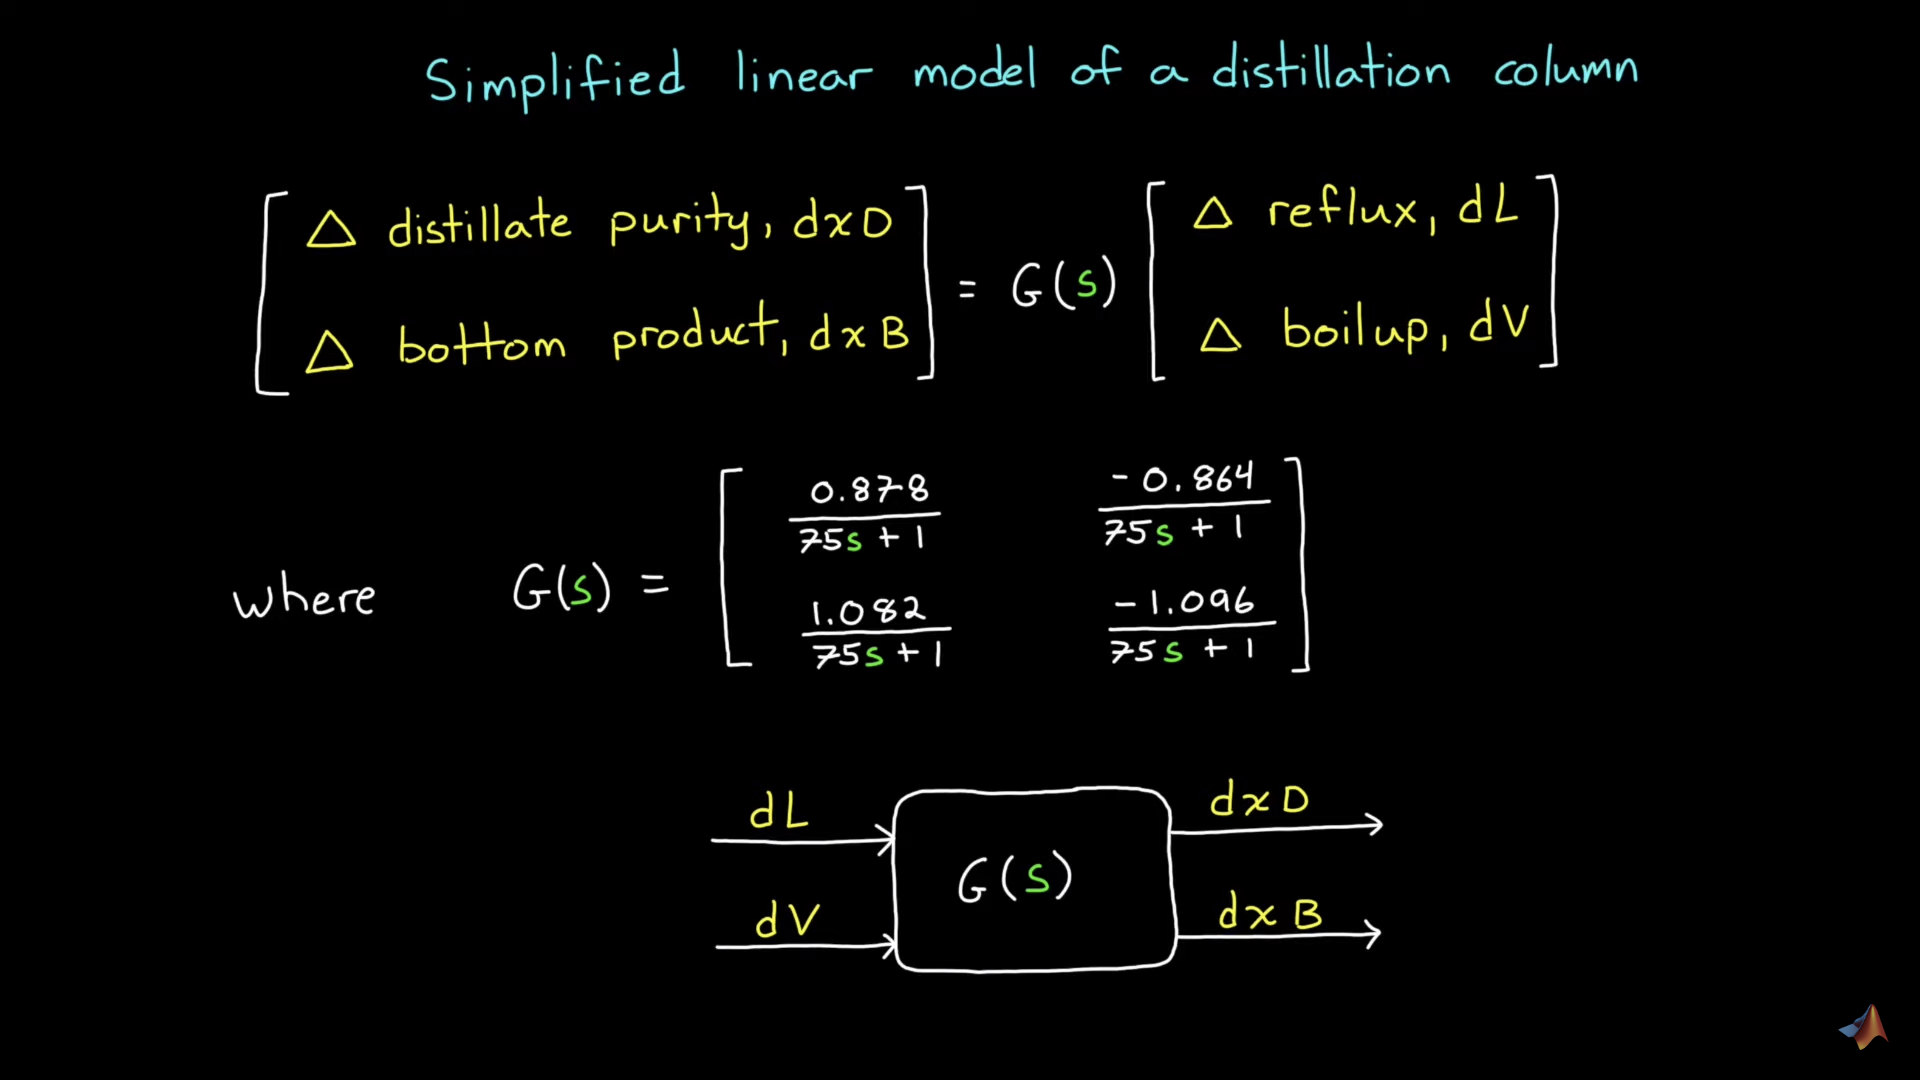

clear;

## Create open loop plant, G

s = tf('s');
tauG = 75;
M = [87.8 -86.4; 108.2 -109.61]/100;
G = 1/(tauG*s + 1)*M

G =
 
  From input 1 to output...
        0.878
   1:  --------
       75 s + 1
 
        1.082
   2:  --------
       75 s + 1
 
  From input 2 to output...
        -0.864
   1:  --------
       75 s + 1
 
        -1.096
   2:  --------
       75 s + 1
 
Continuous-time transfer function.



## The open loop step response for the plant

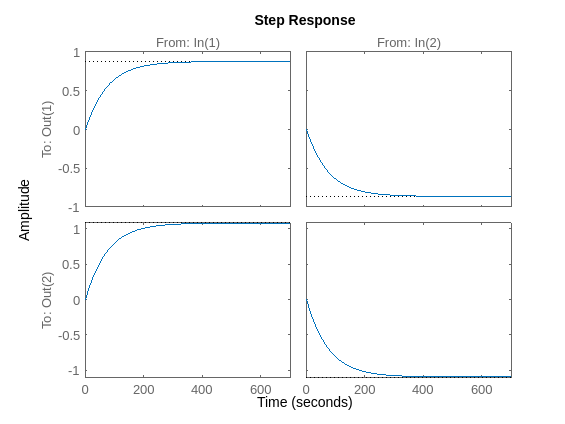

step(G)

## Inversion-based control law

Controller: $C(s)=G(s)^{-1}$

Open loop response, controller + plant: $L(s)=G(s)^{-1}G(s)=I$

C = 1/G;
L = C*G;

## The open loop step response for the plant + controller

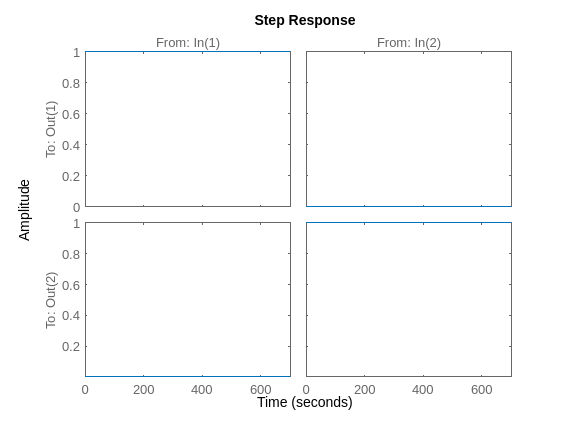

stepplot(L);

## Problem: the controller is not a proper transfer function

display(C);

C =
 
  From input 1 to output...
   1:  2986 s + 39.82
 
   2:  2948 s + 39.31
 
  From input 2 to output...
   1:  -2354 s - 31.39
 
   2:  -2392 s - 31.9
 
Continuous-time transfer function.



### To make the controller proper, we can multiply it by 1/s (integral)

### To have more flexibility, we can multiply by a gain (proportional)

## Inversion-based PI controller

Controller: $C(s)=\frac{k}{s}G(s)^{-1}$

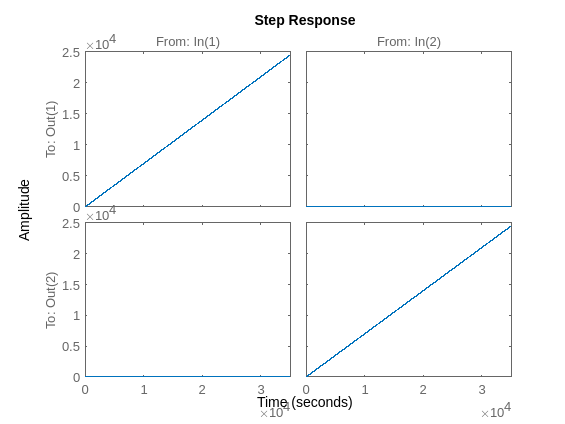

k = 0.7;
C = (k/s)/G;

% Switch to state-space for better numerical conditioning
G = ss(G);
C = ss(C);

stepplot(C*G);

## Closed loop step response

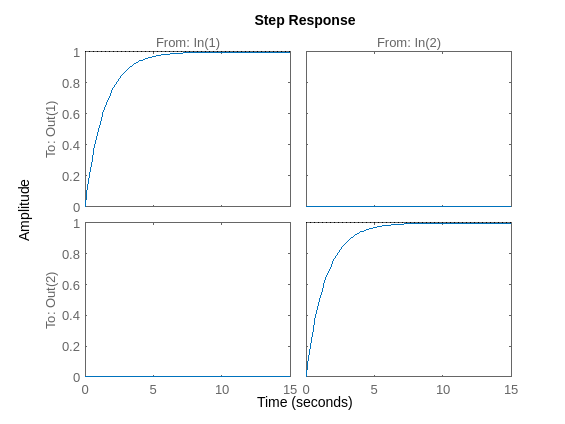

CL = feedback(C*G, eye(2));
stepplot(CL, 15);

## What we have done so far

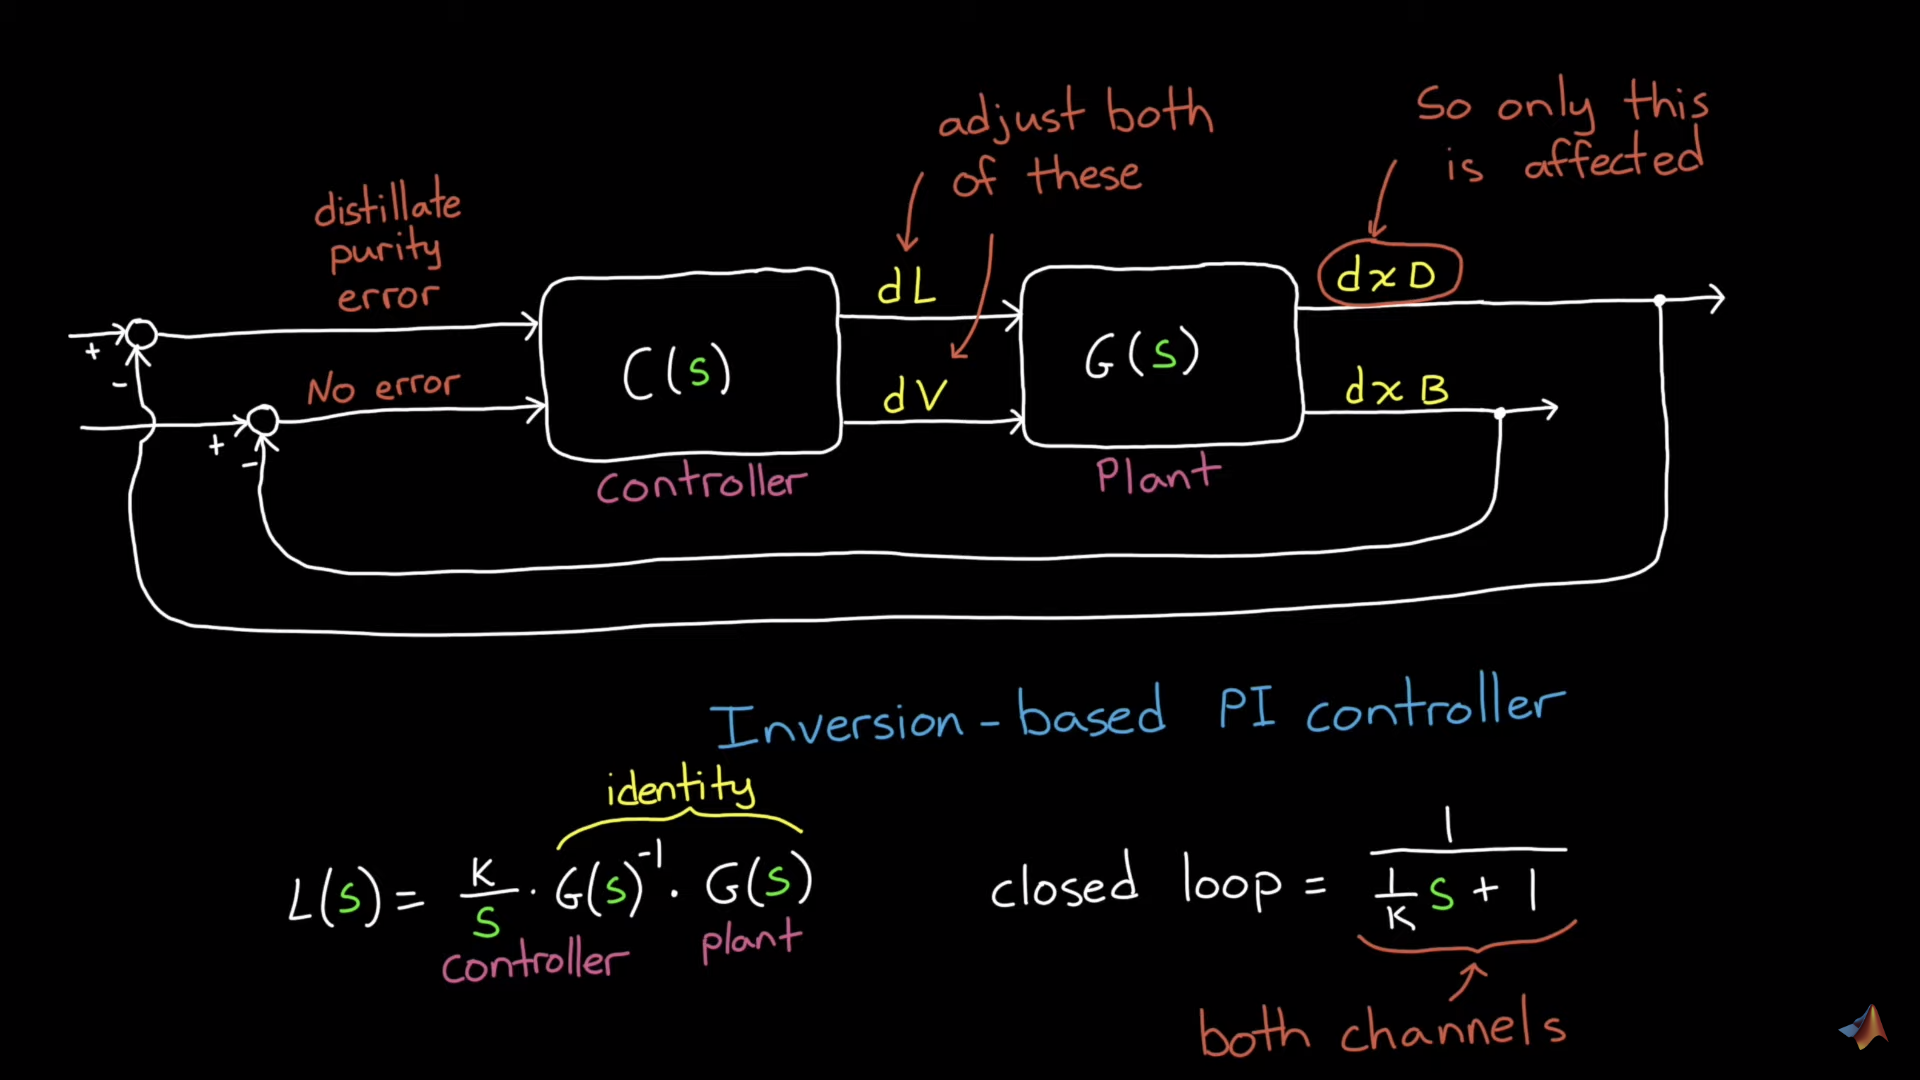

## Robustness

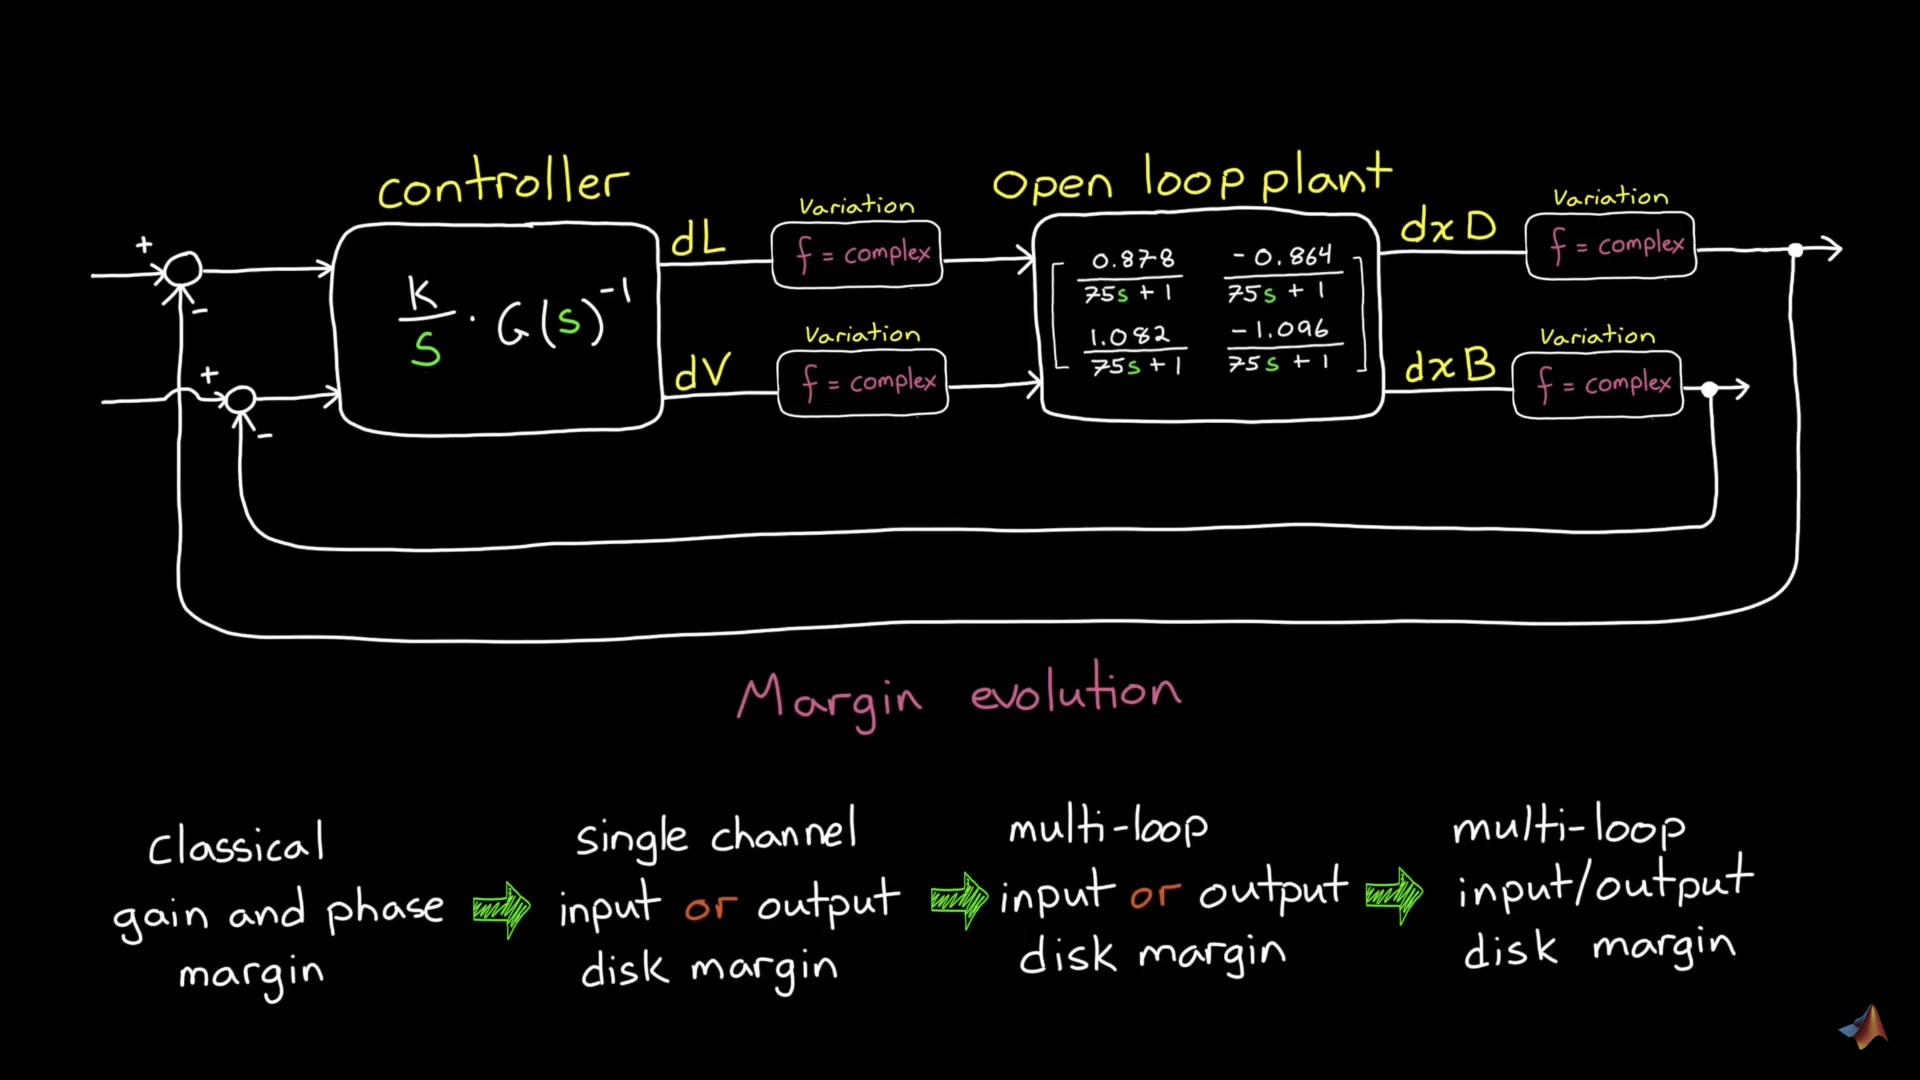

## Disk Margins at Input

[DMI, MMI] = diskmargin(C*G);

### DMI: Loop-at-time input disk margins

display(DMI(1));

  struct with fields:

           GainMargin: [0 Inf]
          PhaseMargin: [-90 90]
           DiskMargin: 2
           LowerBound: 2
           UpperBound: 2
            Frequency: Inf
    WorstPerturbation: [2×2 ss]



display(DMI(2));

  struct with fields:

           GainMargin: [0 4.6912e+13]
          PhaseMargin: [-90.0000 90.0000]
           DiskMargin: 2.0000
           LowerBound: 2.0000
           UpperBound: 2.0000
            Frequency: 0
    WorstPerturbation: [2×2 ss]



### MMI: Multi-loop input disk margins

display(MMI);

MMI = struct with fields:
           GainMargin: [0.0010 978.8159]
          PhaseMargin: [-89.8829 89.8829]
           DiskMargin: 1.9959
           LowerBound: 1.9959
           UpperBound: 2.0000
            Frequency: 1
    WorstPerturbation: [2×2 ss]


## Disk Margins at Output

[DMO, MMO] = diskmargin(G*C);

### DMO: Loop-at-time output disk margins

display(DMO(1));

  struct with fields:

           GainMargin: [0 1.4297e+14]
          PhaseMargin: [-90.0000 90.0000]
           DiskMargin: 2.0000
           LowerBound: 2.0000
           UpperBound: 2.0000
            Frequency: 0.0133
    WorstPerturbation: [2×2 ss]



display(DMO(2));

  struct with fields:

           GainMargin: [0 6.8236e+13]
          PhaseMargin: [-90.0000 90.0000]
           DiskMargin: 2.0000
           LowerBound: 2.0000
           UpperBound: 2.0000
            Frequency: 0
    WorstPerturbation: [2×2 ss]



### MMO: Multi-loop output disk margins

display(MMO);

MMO = struct with fields:
           GainMargin: [0.0010 978.8159]
          PhaseMargin: [-89.8829 89.8829]
           DiskMargin: 1.9959
           LowerBound: 1.9959
           UpperBound: 2.0000
            Frequency: 0
    WorstPerturbation: [2×2 ss]


## Disk Margins at Intput and Output

MMIO = diskmargin(G,C);

### MMIO: Multi-loop concurrent input/output disk margins

display(MMIO);

MMIO = struct with fields:
           GainMargin: [0.8870 1.1273]
          PhaseMargin: [-6.8509 6.8509]
           DiskMargin: 0.1197
           LowerBound: 0.1197
           UpperBound: 0.1200
            Frequency: 0.6996
    WorstPerturbation: [1×1 struct]
